% Final Project - ENGR 25, Fall 2021
% Darren Ho, Seth Miu

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%       Part 1       %%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; clc; close all;

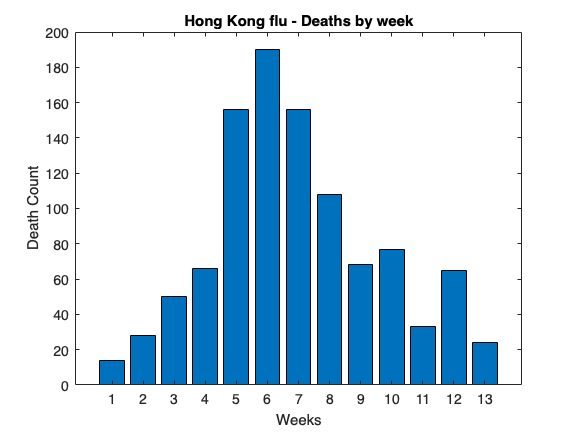

% Background: During the winter of 1968-69, the United States was swept by 
% a virulent new strain of influenza named Hong Kong Flu. 
% At that time, no flu vaccine was available, so many more people were 
% infected than would be the case today. We will study the spread of the 
% disease through a single urban population, New York City. 
% The data displayed in the following table are weekly "excess" 
% pneumonia-influenza deaths, that is, the numbers of such deaths in 
% excess of the average numbers to be expected from other sources. 
% The graph displays the same data (Source: Centers for Disease Control).


%%%%%%%%%%%%%%
%%   Data   %%
%%%%%%%%%%%%%%

week = 1:13; 	
fluDeaths = [14 28 50 66 156 190 156 108 68 77 33 65 24];

bar(week,fluDeaths),xlabel('Weeks'),ylabel('Death Count')
title('Hong Kong flu - Deaths by week')

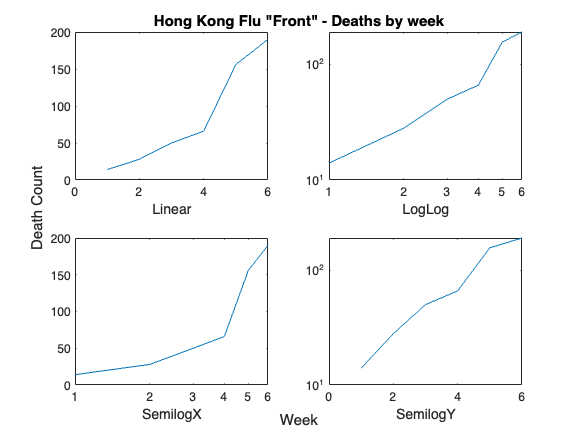

% Instructions: Type up the answers to the following questions on a 
% single text document per group. Answers should be written in clear, 
% grammatically correct English without spelling errors. 
% If appropriate, add any fully commented MATLAB scripts. 
% You will also be including Excel spreadsheets of data.

%%%%%%%%%%%%%%
%%  Step 1  %%
%%%%%%%%%%%%%%

% Create a linear and logarithmic plots of flu related deaths 
% for the "front" of the Hong Kong Flu data above. 
% The front refers to the growth phase, which for this case we will
% consider only the data before the peak (weeks 1-6 for Hong Kong Flu). 

% In the text document, describe which type of equation fits best. 
% What other observations can you make about the trend?

frontWeek = week(1:6);
frontDeaths = fluDeaths(1:6);

fig = figure(2);
subplot(2,2,1)
plot(frontWeek,frontDeaths),xlabel('Linear')

subplot(2,2,2)
loglog(frontWeek,frontDeaths),xlabel('LogLog')

subplot(2,2,3)
semilogx(frontWeek,frontDeaths),xlabel('SemilogX')

subplot(2,2,4)
semilogy(frontWeek,frontDeaths),xlabel('SemilogY')

han=axes(fig,'visible','off'); 
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'Death Count');
xlabel(han,'Week');
title(han,'Hong Kong Flu "Front" - Deaths by week');


% Fit the front to a polynomial equation, a power function, 
% and an exponential function using MATLAB. 

lin_coeff = polyfit(frontWeek,frontDeaths,3);
exp_coeff = polyfit(frontWeek,log(frontDeaths),1);
pwr_coeff = polyfit(log(frontWeek),log(frontDeaths),1);


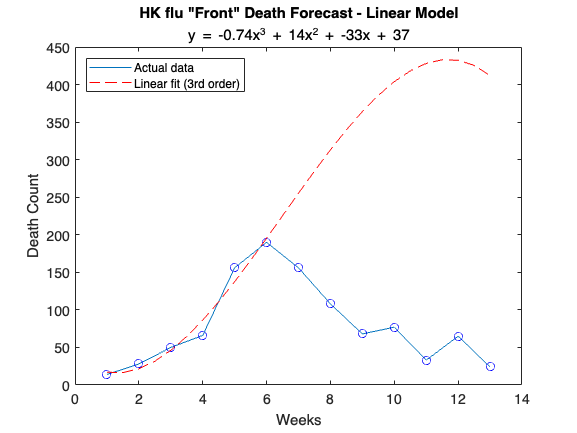

week_plot = linspace(min(week),max(week),25);

figure(3)
plot(week,fluDeaths, week,fluDeaths,'ob')
hold on
plot(week_plot,polyval(lin_coeff,week_plot),'--r')
hold off
legend('Actual data','','Linear fit (3rd order)','Location','Northwest')
xlabel('Weeks'),ylabel('Death Count')
title('HK flu "Front" Death Forecast - Linear Model', ...
    ['y = ', ...
    num2str(lin_coeff(1),2),'x^3 + ', ...
    num2str(lin_coeff(2),2),'x^2 + ', ...
    num2str(lin_coeff(3),2), 'x + ', ...
    num2str(lin_coeff(4),2)])

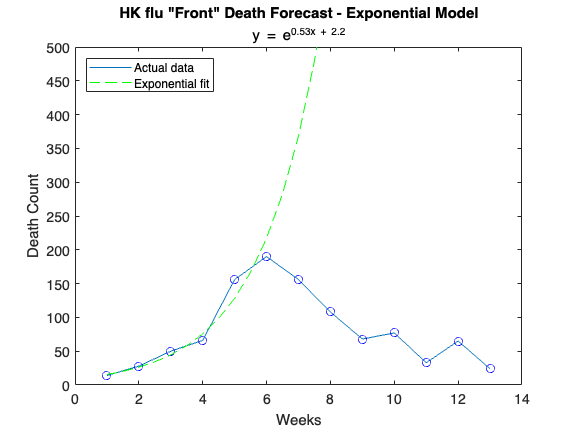



plot(week,fluDeaths, week,fluDeaths,'ob')
hold on
plot(week_plot,exp(polyval(exp_coeff,week_plot)),'--g')
hold off
ylim([0 500])
legend('Actual data','','Exponential fit','Location','Northwest')
xlabel('Weeks'),ylabel('Death Count')
title('HK flu "Front" Death Forecast - Exponential Model', ...
    ['y = e^{', ...
    num2str(exp_coeff(1),2),'x + ', ...
    num2str(exp_coeff(2),2),'}'])

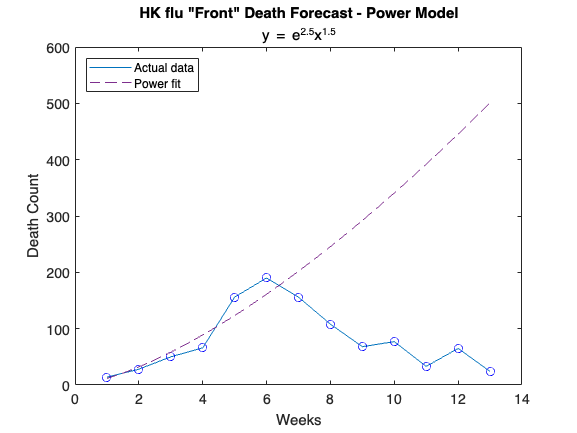



plot(week,fluDeaths, week,fluDeaths,'ob')
hold on
plot(week_plot,exp(pwr_coeff(2)) * week_plot.^pwr_coeff(1),'--','Color','#7E2F8E')
hold off
legend('Actual data','','Power fit','Location','Northwest')
xlabel('Weeks'),ylabel('Death Count')
title('HK flu "Front" Death Forecast - Power Model', ...
    ['y = e^{', ...
    num2str(pwr_coeff(2),2),'}x^{', ...
    num2str(pwr_coeff(1),2),'}'])


% As observed in the model plots, none of the fitted curves are an accurate
% portrayal of the trend of flu - related deaths, since they are only modeled 
% via data during the growth phase or "the front" of the pandemic. 
% This means the forecasts are only accurate  up to "Week 6" of the 
% Hong Kong flu dataset, since they do not take into consideration the 
% dynamic between population contagion, vacinnations, as well as existing deaths 
% (all of which which would diminish the # of deaths caused by the virus). 


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%  Step 2,3,4 are outside of MATLAB  %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

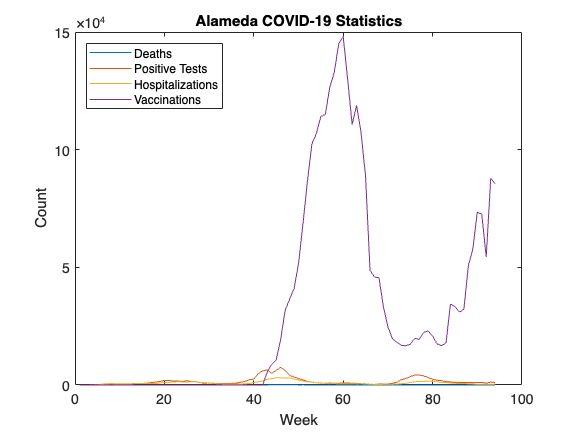

%%%%%%%%%%%%%%
%%  Step 5  %%
%%%%%%%%%%%%%%

% In MATLAB, use xlsread or similar to load the data from your spreadsheet(s). 
% In MATLAB, plot the following quantities for both of your locations. 
% The x-axis should be “Weeks since first positive test” and the y-axis will 
% reflect the data. You may create as little or as many plots as necessary, 
% as long as they are fully labeled and use appropriate data markers. 
%   a. Weeks vs. Positive COVID-19 tests 
%   b. Weeks vs. COVID-19 deaths 
%   c. Weeks vs. COVID-19 hospitalizations 
%   d. Weeks vs. COVID-19 vaccinations 

warning('off')

Alameda_df = readtable('Data_Part1_v4.xlsx','Sheet','Alameda');
LA_df = readtable('Data_Part1_v4.xlsx','Sheet','LA');

Alameda_wf = groupsummary(Alameda_df(:,1:end-1),'Date','week','sum');
LA_wf = groupsummary(LA_df(:,1:end-1),'Date','week','sum');


plot(1:length(Alameda_wf.week_Date),Alameda_wf.sum_Deaths)
hold on
plot(1:length(Alameda_wf.week_Date),Alameda_wf.sum_PositiveTests)
plot(1:length(Alameda_wf.week_Date),Alameda_wf.sum_Hospitalizations)
plot(1:length(Alameda_wf.week_Date),Alameda_wf.sum_Vaccinations)
hold off
xlabel('Week')
ylabel('Count')
title('Alameda COVID-19 Statistics')
legend('Deaths','Positive Tests','Hospitalizations','Vaccinations','Location','Northwest')

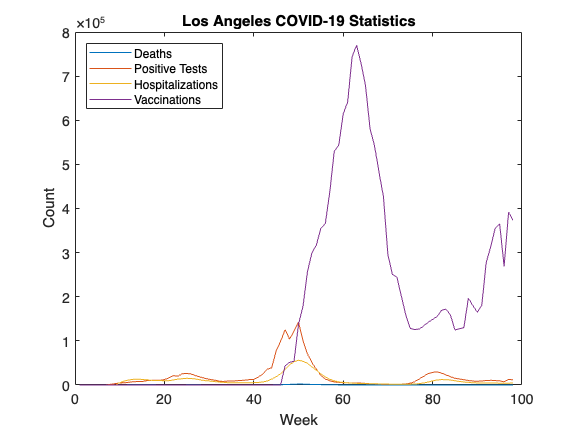



plot(1:length(LA_wf.week_Date),LA_wf.sum_Deaths)
hold on
plot(1:length(LA_wf.week_Date),LA_wf.sum_PositiveTests)
plot(1:length(LA_wf.week_Date),LA_wf.sum_Hospitalizations)
plot(1:length(LA_wf.week_Date),LA_wf.sum_Vaccinations)
hold off
xlabel('Week')
ylabel('Count')
title('Los Angeles COVID-19 Statistics')
legend('Deaths','Positive Tests','Hospitalizations','Vaccinations','Location','Northwest')

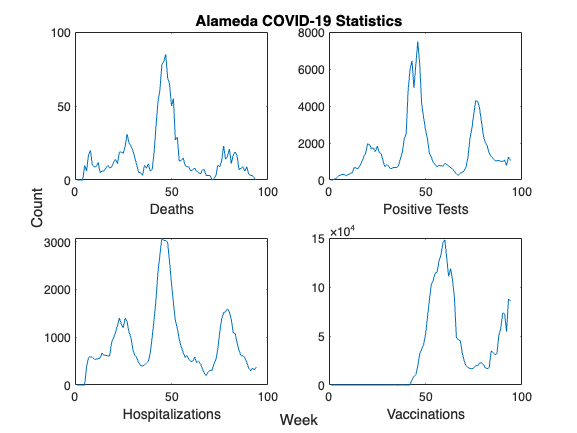

fig = figure(8);

subplot(2,2,1)
plot(1:length(Alameda_wf.week_Date),Alameda_wf.sum_Deaths)
xlabel('Deaths')

subplot(2,2,2)
plot(1:length(Alameda_wf.week_Date),Alameda_wf.sum_PositiveTests)
xlabel('Positive Tests')

subplot(2,2,3)
plot(1:length(Alameda_wf.week_Date),Alameda_wf.sum_Hospitalizations)
xlabel('Hospitalizations')

subplot(2,2,4)
plot(1:length(Alameda_wf.week_Date),Alameda_wf.sum_Vaccinations)
xlabel('Vaccinations')

han=axes(fig,'visible','off'); 
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'Count');
xlabel(han,'Week');
title(han,'Alameda COVID-19 Statistics');

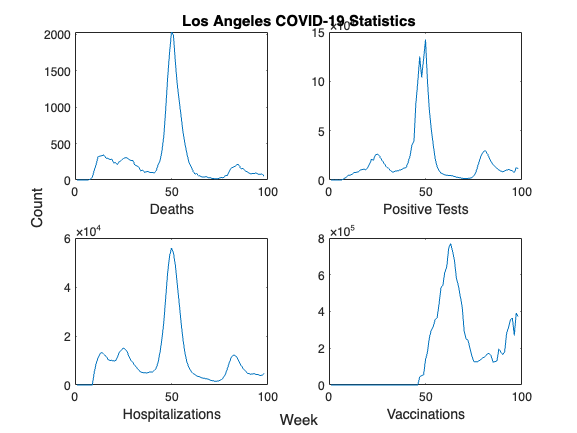



fig = figure(9);

subplot(2,2,1)
plot(1:length(LA_wf.week_Date),LA_wf.sum_Deaths)
xlabel('Deaths')

subplot(2,2,2)
plot(1:length(LA_wf.week_Date),LA_wf.sum_PositiveTests)
xlabel('Positive Tests')

subplot(2,2,3)
plot(1:length(LA_wf.week_Date),LA_wf.sum_Hospitalizations)
xlabel('Hospitalizations')

subplot(2,2,4)
plot(1:length(LA_wf.week_Date),LA_wf.sum_Vaccinations)
xlabel('Vaccinations')

han=axes(fig,'visible','off'); 
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'Count');
xlabel(han,'Week')
title(han,'Los Angeles COVID-19 Statistics');

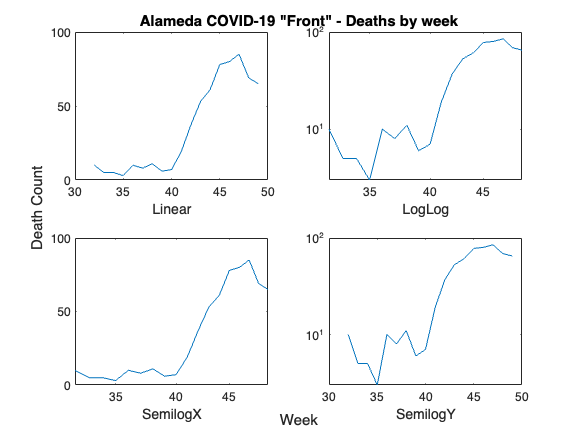

%%%%%%%%%%%%%%
%%  Step 6  %%
%%%%%%%%%%%%%%

% Repeat Question 1 but with the death data you found for Alameda County. 
% For this analysis, you may focus on the front of the data for the 
% peak between October 2020 and January 2021. 
% Do not use the entire dataset as your models will not be applicable.


% Weeks: Sep 27 2020 - Jan 31 2021
Alameda_front = Alameda_wf(32:49,:); 


fig = figure(10);
subplot(2,2,1)
plot(32:49,Alameda_front.sum_Deaths),xlabel('Linear')

subplot(2,2,2)
loglog(32:49,Alameda_front.sum_Deaths),xlabel('LogLog')

subplot(2,2,3)
semilogx(32:49,Alameda_front.sum_Deaths),xlabel('SemilogX')

subplot(2,2,4)
semilogy(32:49,Alameda_front.sum_Deaths),xlabel('SemilogY')

han=axes(fig,'visible','off'); 
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'Death Count');
xlabel(han,'Week');
title(han,'Alameda COVID-19 "Front" - Deaths by week');

week_plot = 1:length(Alameda_wf.week_Date);

lin_coeff = polyfit(32:49,Alameda_front.sum_Deaths,3);
exp_coeff = polyfit(32:49,log(Alameda_front.sum_Deaths),1);
pwr_coeff = polyfit(log(32:49),log(Alameda_front.sum_Deaths),1);


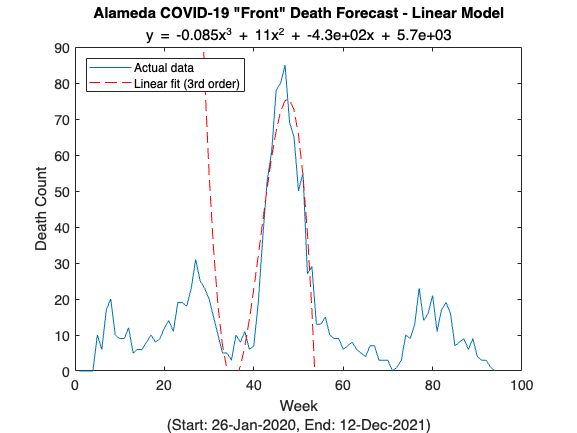

figure(11)
plot(week_plot,Alameda_wf.sum_Deaths)
hold on
plot(week_plot,polyval(lin_coeff,week_plot),'--r')
ylim([0 90])
hold off
legend('Actual data','Linear fit (3rd order)','Location','Northwest')
xlabel({'Week', '(Start: 26-Jan-2020, End: 12-Dec-2021)'}),ylabel('Death Count')
title('Alameda COVID-19 "Front" Death Forecast - Linear Model', ...
    ['y = ', ...
    num2str(lin_coeff(1),2),'x^3 + ', ...
    num2str(lin_coeff(2),2),'x^2 + ', ...
    num2str(lin_coeff(3),2), 'x + ', ...
    num2str(lin_coeff(4),2)])

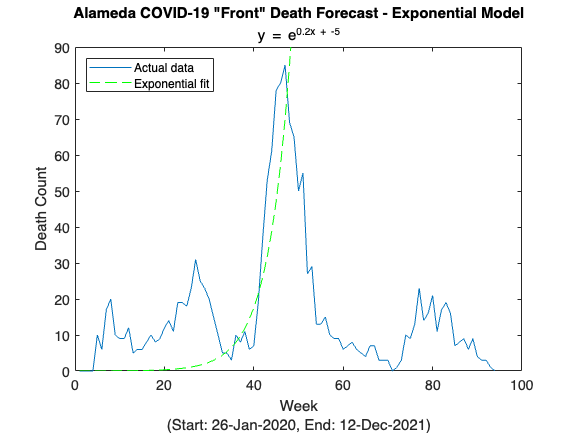



plot(week_plot,Alameda_wf.sum_Deaths)
hold on
plot(week_plot,exp(polyval(exp_coeff,week_plot)),'--g')
hold off
ylim([0 90])
legend('Actual data','Exponential fit','Location','Northwest')
xlabel({'Week', '(Start: 26-Jan-2020, End: 12-Dec-2021)'}),ylabel('Death Count')
title('Alameda COVID-19 "Front" Death Forecast - Exponential Model', ...
    ['y = e^{', ...
    num2str(exp_coeff(1),2),'x + ', ...
    num2str(exp_coeff(2),2),'}'])

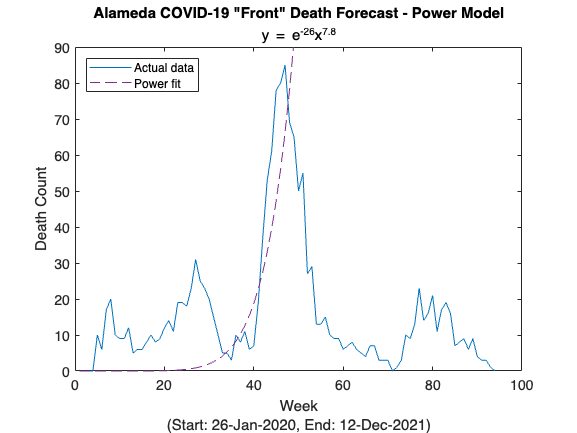



plot(week_plot,Alameda_wf.sum_Deaths)
hold on
plot(week_plot,exp(pwr_coeff(2)) * week_plot.^pwr_coeff(1),'--','Color','#7E2F8E')
ylim([0 90])
hold off
legend('Actual data','Power fit','Location','Northwest')
xlabel({'Week', '(Start: 26-Jan-2020, End: 12-Dec-2021)'}),ylabel('Death Count')
title('Alameda COVID-19 "Front" Death Forecast - Power Model', ...
    ['y = e^{', ...
    num2str(pwr_coeff(2),2),'}x^{', ...
    num2str(pwr_coeff(1),2),'}'])

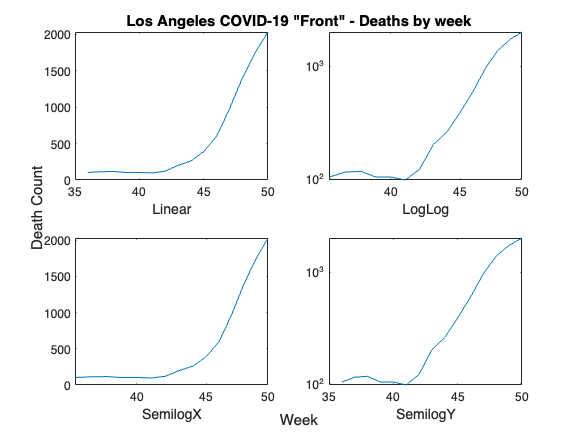

%%%%%%%%%%%%%%
%%  Step 7  %%
%%%%%%%%%%%%%%

% Repeat Question 1 but with the death data you found for the city or 
% county of your choosing. If your chosen city or county has a large 
% peak (like Alameda County's between October 2020 and January 2021), 
% focus on the front of the peak only as you did in step 6. 

% Utilize similar "Front" period due to geographic proximity to Alameda
% Weeks: Sep 27 2020 - Jan 10 2021


LA_front = LA_wf(36:50,:); 

fig = figure(14);
subplot(2,2,1)
plot(36:50,LA_front.sum_Deaths),xlabel('Linear')

subplot(2,2,2)
loglog(36:50,LA_front.sum_Deaths),xlabel('LogLog')

subplot(2,2,3)
semilogx(36:50,LA_front.sum_Deaths),xlabel('SemilogX')

subplot(2,2,4)
semilogy(36:50,LA_front.sum_Deaths),xlabel('SemilogY')

han=axes(fig,'visible','off'); 
han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'Death Count');
xlabel(han,'Week');
title(han,'Los Angeles COVID-19 "Front" - Deaths by week');


week_plot = 1:length(LA_wf.week_Date);

lin_coeff = polyfit(36:50,LA_front.sum_Deaths,3);
exp_coeff = polyfit(36:50,log(LA_front.sum_Deaths),1);
pwr_coeff = polyfit(log(36:50),log(LA_front.sum_Deaths),1);


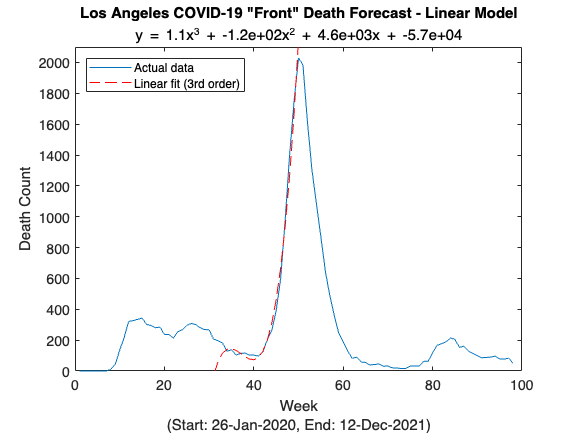

figure(15)
plot(week_plot,LA_wf.sum_Deaths)
hold on
plot(week_plot,polyval(lin_coeff,week_plot),'--r')
ylim([0 2100])
hold off
legend('Actual data','Linear fit (3rd order)','Location','Northwest')
xlabel({'Week', '(Start: 26-Jan-2020, End: 12-Dec-2021)'}),ylabel('Death Count')
title('Los Angeles COVID-19 "Front" Death Forecast - Linear Model', ...
    ['y = ', ...
    num2str(lin_coeff(1),2),'x^3 + ', ...
    num2str(lin_coeff(2),2),'x^2 + ', ...
    num2str(lin_coeff(3),2), 'x + ', ...
    num2str(lin_coeff(4),2)])

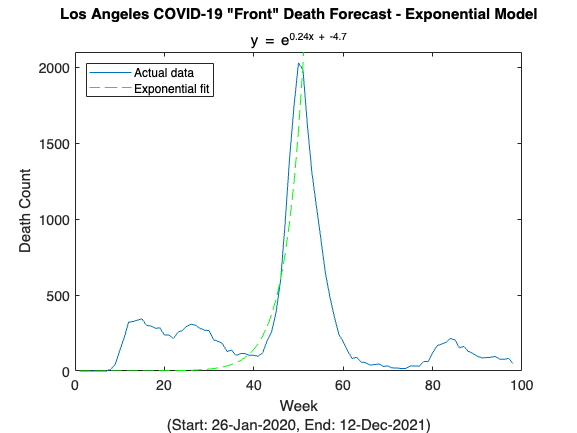



plot(week_plot,LA_wf.sum_Deaths)
hold on
plot(week_plot,exp(polyval(exp_coeff,week_plot)),'--g')
hold off
ylim([0 2100])
legend('Actual data','Exponential fit','Location','Northwest')
xlabel({'Week', '(Start: 26-Jan-2020, End: 12-Dec-2021)'}),ylabel('Death Count')
title('Los Angeles COVID-19 "Front" Death Forecast - Exponential Model', ...
    ['y = e^{', ...
    num2str(exp_coeff(1),2),'x + ', ...
    num2str(exp_coeff(2),2),'}'])

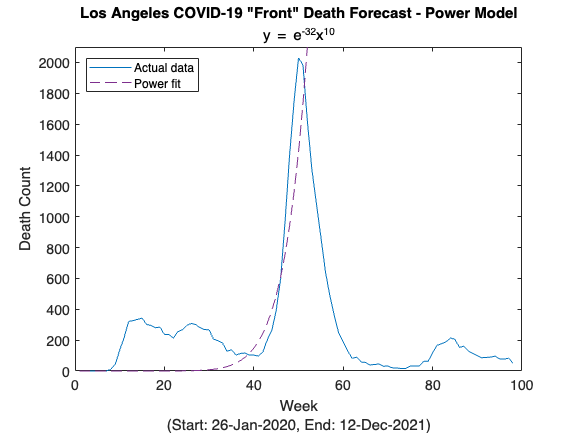



plot(week_plot,LA_wf.sum_Deaths)
hold on
plot(week_plot,exp(pwr_coeff(2)) * week_plot.^pwr_coeff(1),'--','Color','#7E2F8E')
ylim([0 2100])
hold off
legend('Actual data','Power fit','Location','Northwest')
xlabel({'Week', '(Start: 26-Jan-2020, End: 12-Dec-2021)'}),ylabel('Death Count')
title('Los Angeles COVID-19 "Front" Death Forecast - Power Model', ...
    ['y = e^{', ...
    num2str(pwr_coeff(2),2),'}x^{', ...
    num2str(pwr_coeff(1),2),'}'])